## **Arenstorf Orbit**

clear
close
clc

set(groot, "defaultAxesTickLabelInterpreter", "latex");
set(groot, "defaultTextInterpreter", "latex");
set(groot, "defaultLegendInterpreter", "latex");
set(groot, "defaultColorbarTickLabelInterpreter", "latex");

mu = 0.012277471;
mu_prime = 1 - mu;

dzdt_anon = @(t, z) [z(3);
          z(4);
          z(1) + 2*z(4) + (mu*(mu_prime - z(1)))/((mu_prime - z(1))^2 + z(2)^2)^(3/2) - (mu_prime*(mu + z(1)))/((mu + z(1))^2 + z(2)^2)^(3/2);
          z(2) - 2*z(3) - (mu_prime*z(2))/((mu + z(1))^2 + z(2)^2)^(3/2) - (mu*z(2))/((mu_prime - z(1))^2 + z(2)^2)^(3/2)];

incond = [0.994; 0; 0; -2.00158510637908252240537862224];
tspan = [0 17.0652165601579625588917206249];

ATol = 1e-12;
Rtol = 1e-12;

[tsol, zsol, dzdt_eval, stats] = odeEmbeddedSolvers(dzdt_anon, tspan, incond, "ATol", ATol, "Rtol", Rtol, "Method", "Tsit5(4)7*");
stats

stats = struct with fields:
            n_feval: 17125
    n_success_steps: 2854
     n_failed_steps: 0
        tau_history: [2855×1 double]
      error_history: [2855×1 double]


-log10(abs(zsol(end, :)-zsol(1, :))).'

ans =           11.5513491051065
          11.1402071311517
          8.92571098780612
          9.35895512528315


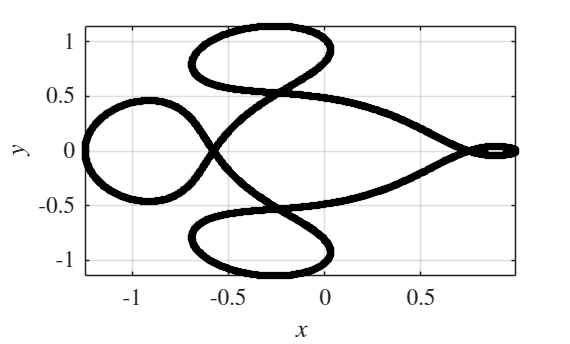

figure
plot(zsol(:, 1), zsol(:, 2), '-ok', 'LineWidth', 1.5, 'MarkerSize', 3)
xlabel("$x$")
ylabel("$y$")
axis tight
box on
grid on
set(gca, "FontSize", 14)

% exportgraphics(gcf, "images/ArenstorfOrbit.svg", "ContentType","vector")